clear
table = readtable("../cpp/output/coordinateOutput.csv")

table = 608001×6 table
    simulationID    particleID    depth        x            y          z   
    ____________    __________    _____    _________    _________    ______

         2              0           0       0.039398    -0.025578    2.2759
         2              0           0       0.032623    -0.073662    4.5518
         2              0           0       0.067092     -0.16609     6.826
         2              0           0       0.017694     -0.21599    9.1013
         2              0           0      -0.074541     -0.28232    11.375
         2              0           0       -0.27038     -0.35091    13.642
         2              0           0       -0.37889     -0.18571     15.91
         2              0           0       -0.47487      -0.0685    18.181
         2  

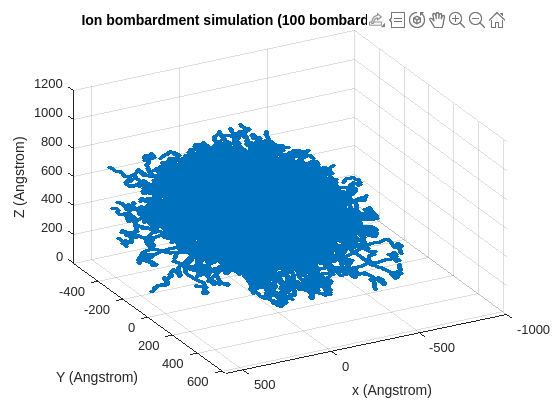

clf; 

filter = false;
    
% Define marker size
marker_size = 10; % Adjust as needed

if filter
    target =  0;
    filtered1 = table(table.depth == target, :)
    startidx = 0;
    idx = size(filtered1, 1)
    % idx = 471742
    x = filtered1.x(startidx:idx);
    y = filtered1.y(startidx:idx);
    z = filtered1.z(startidx:idx);
else
    x = table.x;
    y = table.y;
    z = table.z;
end

scatter3(x, y, z, marker_size, 'filled')
% plot3(x,y,z);
xlabel("x (Angstrom)")
ylabel("Y (Angstrom)")
zlabel("Z (Angstrom)")
title("Ion bombardment simulation (100 bombardments, cascade on)");
view([3,3,1])
% view([0, 0])
grid on;

% xlim([-150,150])
% ylim([-150,150])
% zlim([0, 1000])

% clf;
% 
% while true
%     THETA0 = pi/6;
%     ALPHA0 = 0;
%     THETA1RELATIVE = rand()*pi;
%     THETA2RELATIVE = 0;
% 
%     [THETA0, ALPHA0] = AMAGIC(THETA0, ALPHA0, THETA1RELATIVE, THETA2RELATIVE)
% 
%     if THETA0 > pi/2
%         disp("Turned!")
%     else
%         disp("Forward.")
%     end
% end

function [THETA1, ALPHA1, THETA2, ALPHA2] = AMAGIC(THETAO, ALPHAO, THETA1RELATIVE, THETA2RELATIVE)
    PI = pi; % Define PI constant

    ALPHA1RELATIVE = rand() * 2 * PI;
    ALPHA2RELATIVE = ALPHA1RELATIVE + PI;

    % For Primary Ion
    X1 = sin(THETA1RELATIVE) * cos(ALPHA1RELATIVE);
    Y1 = sin(THETA1RELATIVE) * sin(ALPHA1RELATIVE);
    Z1 = cos(THETA1RELATIVE);

    Y0 = Y1 * cos(THETAO) + Z1 * sin(THETAO);
    Z0 = -Y1 * sin(THETAO) + Z1 * cos(THETAO);
    X0 = X1;

    Z = Z0;
    X = X0 * sin(ALPHAO) + Y0 * cos(ALPHAO);
    Y = -X0 * cos(ALPHAO) + Y0 * sin(ALPHAO);

    if Z > 0
        THETA1 = atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    elseif Z == 0
        THETA1 = PI / 2;
    else
        THETA1 = PI + atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    end

    if sin(THETA1) ~= 0
        if X > 0
            ALPHA1 = atan(Y / X);
        elseif X == 0
            ALPHA1 = PI - sign(Y) * PI / 2;
        else
            ALPHA1 = PI + atan(Y / X);
        end
    else
        ALPHA1 = 0;
    end

    % For Recoil Target Ion
    X1 = sin(THETA2RELATIVE) * cos(ALPHA2RELATIVE);
    Y1 = sin(THETA2RELATIVE) * sin(ALPHA2RELATIVE);
    Z1 = cos(THETA2RELATIVE);

    Y0 = Y1 * cos(THETAO) + Z1 * sin(THETAO);
    Z0 = -Y1 * sin(THETAO) + Z1 * cos(THETAO);
    X0 = X1;

    Z = Z0;
    X = X0 * sin(ALPHAO) + Y0 * cos(ALPHAO);
    Y = -X0 * cos(ALPHAO) + Y0 * sin(ALPHAO);

    if Z > 0
        THETA2 = atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    elseif Z == 0
        THETA2 = PI / 2;
    else
        THETA2 = PI + atan(sqrt(X ^ 2 + Y ^ 2) / Z);
    end

    if sin(THETA2) ~= 0
        if X > 0
            ALPHA2 = atan(Y / X);
        elseif X == 0
            ALPHA2 = PI - sign(Y) * PI / 2;
        else
            ALPHA2 = PI + atan(Y / X);
        end
    else
        ALPHA2 = 0;
    end
end